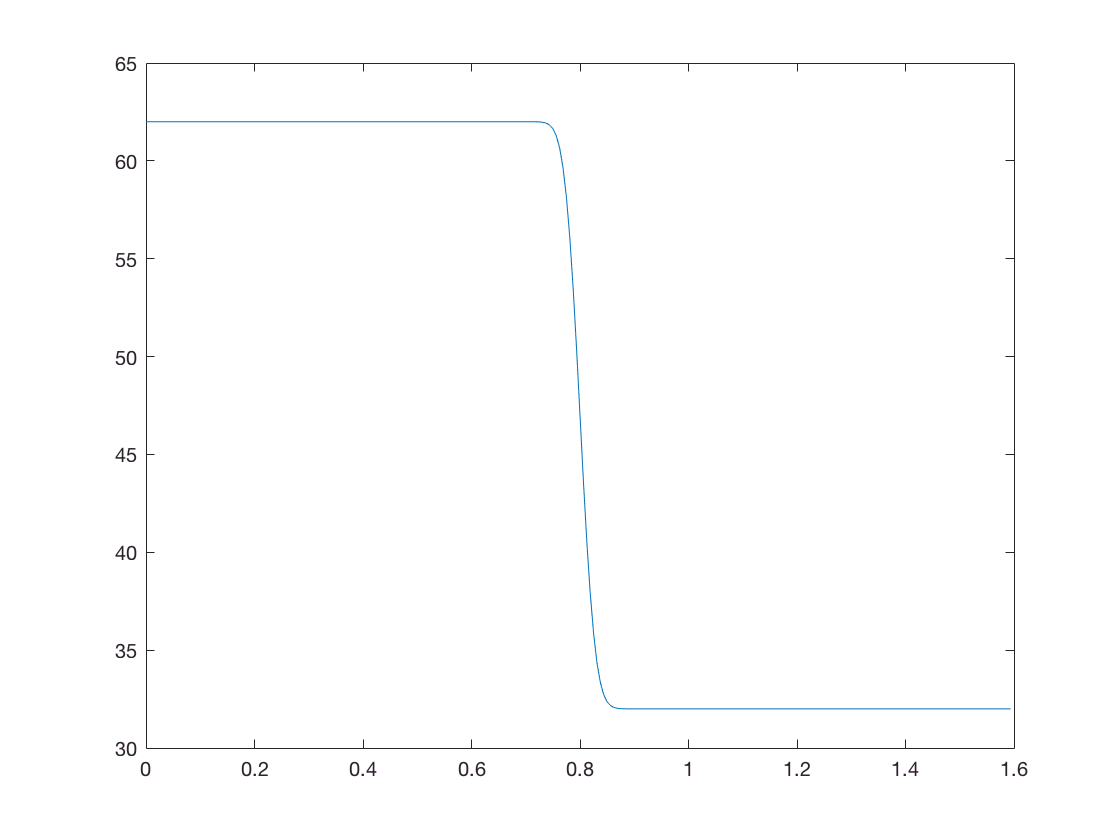

nz=256;
nzarr=1:nz;
Lz=1.6;
z0=Lz/2;
gamma=0.8;
%temp2 is upper tempeartur
%temp1 is lower temperatre
temp2=32;
temp1=62;
zz1=0:Lz/nz:Lz/2-Lz/nz; 
zz2=Lz/2:Lz/nz:Lz-Lz/nz;
zz=[zz1,zz2];

temparr=temp1-0.5*(1+erf(([zz1,zz2]-z0)/(5*Lz/nz)))*(temp1-temp2);
g=1;
p0=2;
zz=[zz1,zz2];
press2=exp(-g*zz2/(gamma*temp2))+p0;
press1=exp(-g*zz1/(gamma*temp1));
press1=exp(-g*zz1/(gamma*temp1))+press2(1)-press1(nz/2);
%plot(zz,[press1, press2])
%plot(zz,[rho1, rho2])
plot(zz,temparr);


press2ext=exp(-g*zz/(gamma*temp2))+p0;
press_temp1=exp(-g*zz/(gamma*temp1));
press_temp2=press2ext(nz/2)-press_temp1(nz/2);
press1ext=press_temp1+press_temp2;
rho1ext=press1ext/(gamma*temp1);
rho2ext=press2ext/(gamma*temp2);

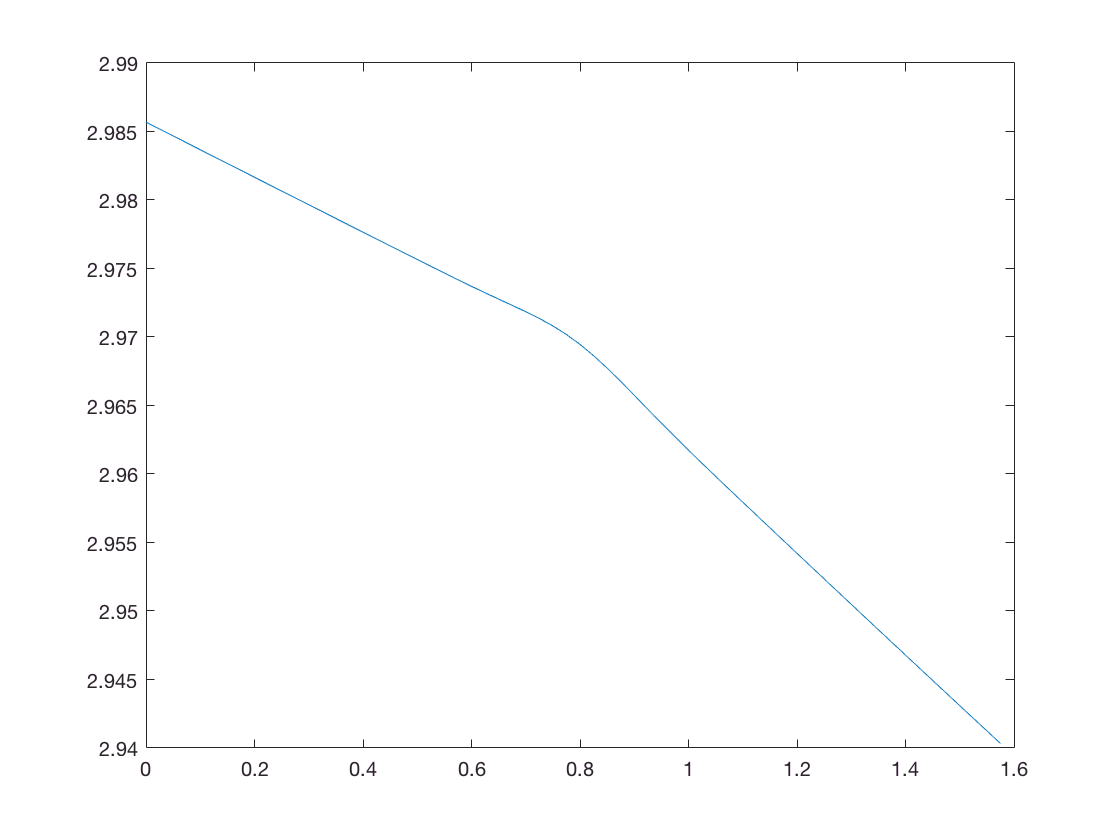

smoothpress=press1ext+0.5*(1+erf((zz-z0)/(5*Lz/nz))).*(press2ext-press1ext);
plot(zz,smoothpress);

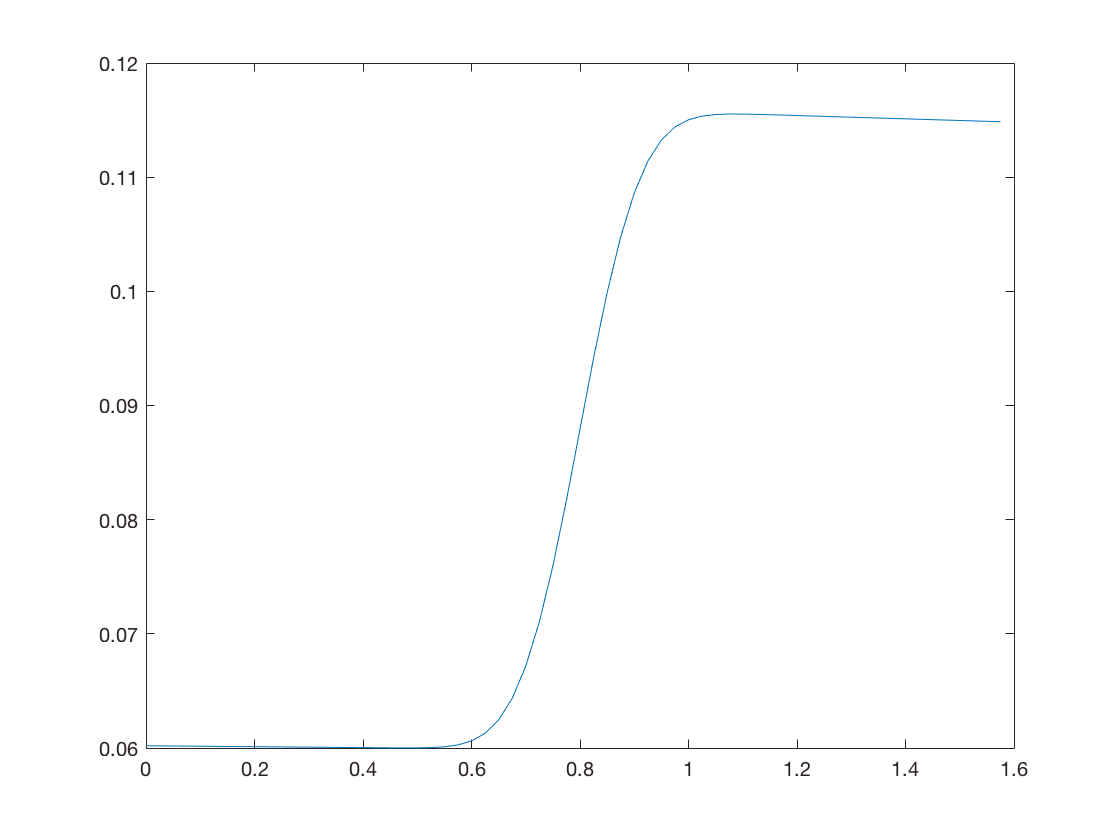

smoothrho=rho1ext+0.5*(1+erf((zz-z0)/(5*Lz/nz))).*(rho2ext-rho1ext);
plot(zz,smoothrho);